clc; clear all; close all;
% Load Data
data = readtable('data/Spectral_Soft_Sensor_1.csv', 'ReadVariableNames', true);

disp(data.Properties.VariableNames(1:21)')

    {'Var1'                      }
    {'AnthocyaninContent__g_cm__'}
    {'BoronContent_mg_cm__'      }
    {'CContent_mg_cm__'          }
    {'CaContent_mg_cm__'         }
    {'CarotenoidContent__g_cm__' }
    {'Cellulose_mg_cm__'         }
    {'ChlContent__g_cm__'        }
    {'CopperContent_mg_cm__'     }
    {'EWT_mg_cm__'               }
    {'Fiber_mg_cm__'             }
    {'LAI_m__m__'                }
    {'LMA_g_m__'                 }
    {'Lignin_mg_cm__'            }
    {'MagnesiumContent_mg_cm__'  }
    {'ManganeseContent_mg_cm__'  }
    {'NContent_mg_cm__'          }
    {'NSC_mg_cm__'               }
    {'PhosphorusContent_mg_cm__' }
    {'PotassiumContent_mg_cm__'  }



data.Var1 = [];

%% Selection of Traits - Based on missing values
traitALL = data.Properties.VariableNames(1:20);

Loaded dataset: 12180 samples, 1721 spectral bands, 5 traits


traits = varfun(@(x) str2double(string(x)), data(:, traitALL));
traits = table2array(traits);

missingPct = mean(isnan(traits), 1) * 100;

[sortedPct, sortIdx] = sort(missingPct, 'ascend');
sortedTraits = traitALL(sortIdx);

traits = sortedTraits(1:5);

disp(table(sortedTraits', sortedPct', 'VariableNames', {'Trait','MissingPercent'}));
fprintf('\nSelected Traits:\n');
disp(traits');

% Splitting as X and Y
traitNames = {'LMA_g_m__', 'NContent_mg_cm__', ...

    TraitIndex    MissingCount    MissingPercent
    __________    ____________    ______________

        1             4266            35.025    
        2             6831            56.084    
        3             7478            61.396    
        4             7983            65.542    
        5             6664            54.713    



              'CContent_mg_cm__', 'ChlContent__g_cm__', 'EWT_mg_cm__'};
% IMPORTANT: Brief explanations of these contents would look good in the report

% Spectral bands
X = table2array(varfun(@(x) str2double(string(x)), data(:, 21:end))); % spectral bands start from column 21

% Traits
Y = table2array(data(:, traitNames));

traits = {'LMA (g/m²)', 'N content (mg/cm²)', ...
          'C content (mg/cm²)', 'Chl content (μg/cm²)', 'EWT (mg/cm²)'};

fprintf('Loaded dataset: %d samples, %d spectral bands, %d traits\n', ...
        size(X,1), size(X,2), size(Y,2));

% Remove rows where any of the traits are missing
idx_validSamples = all(~isnan(Y), 2);
X = X(idx_validSamples, :);
Y = Y(idx_validSamples, :);

fprintf('Valid samples: %d\n', size(X,1));

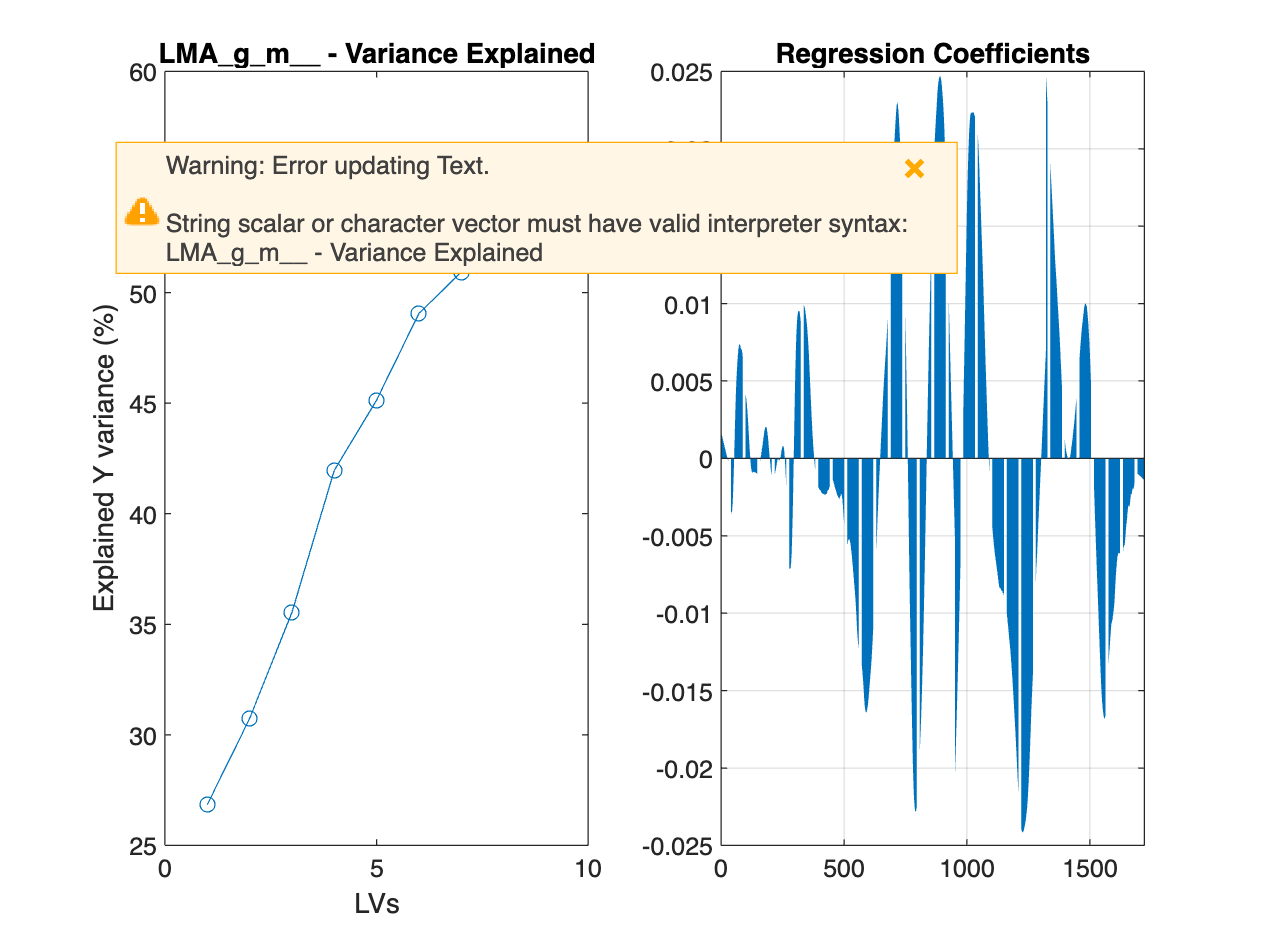

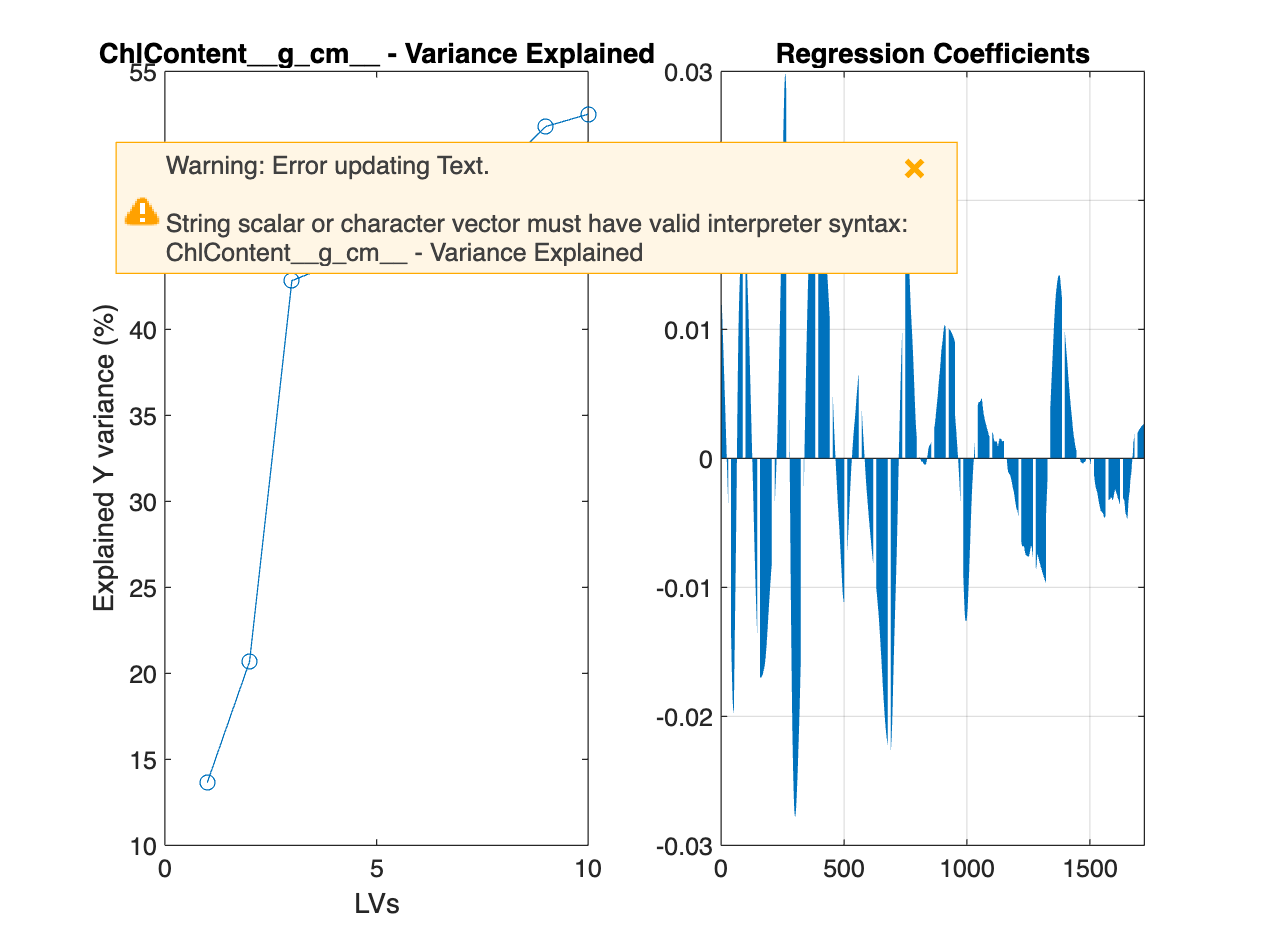

Skipping EWT_mg_cm__ (too many NaNs)
Skipping Fiber_mg_cm__ (too many NaNs)


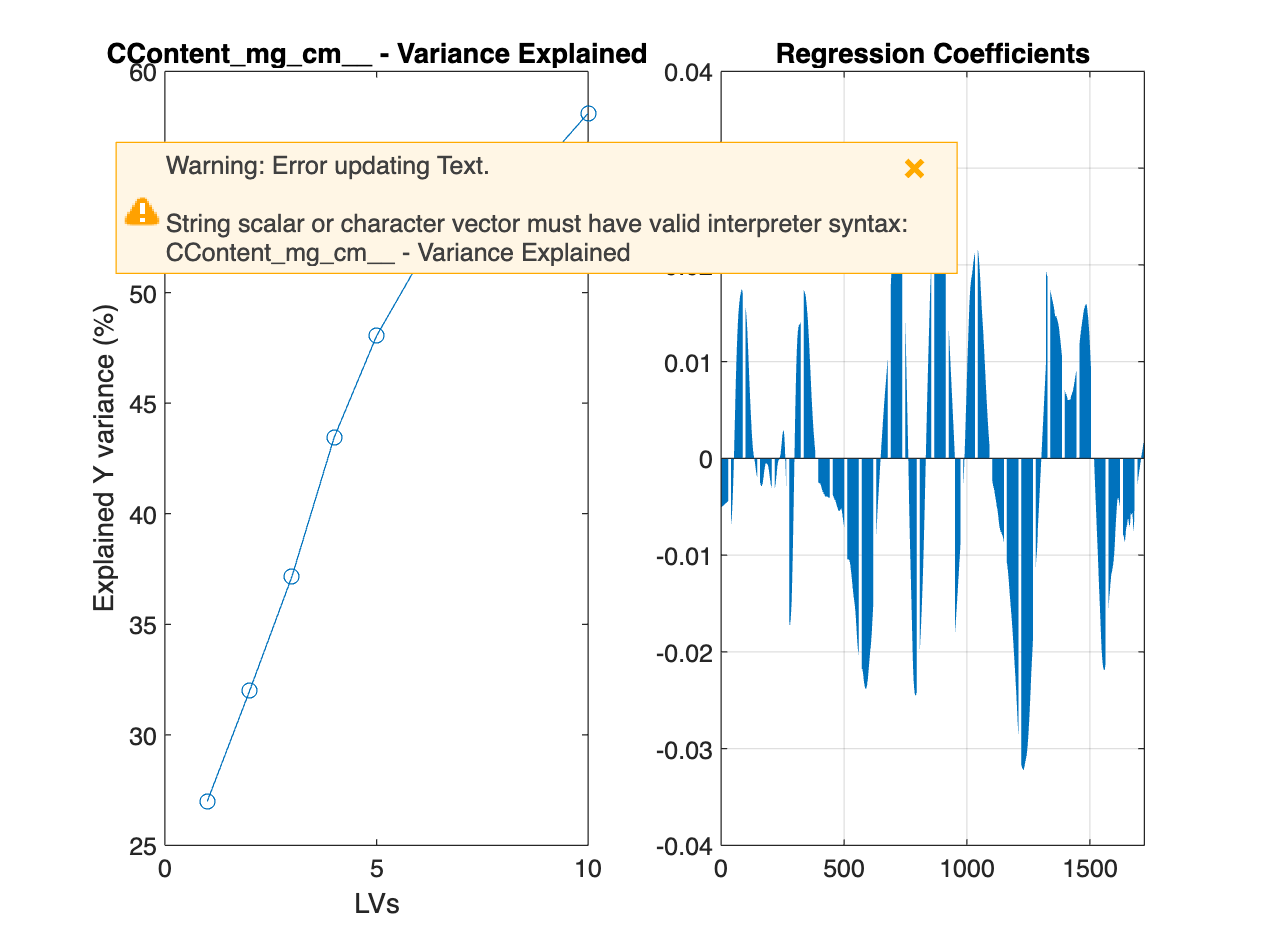

%% Train - Test Split (Stratified Sampling - %80:%20)
rng(42);  

y_mean = mean(Y, 2);  % average trait value per sample
nBins = 10;
[~,~,binIdx] = histcounts(y_mean, nBins);

% Random selection(%80-%20)
trainR = false(size(Y,1),1);

for b = 1:nBins
    binSamples = find(binIdx == b);
    if numel(binSamples) < 2
        continue  
    end
    nTrainBin = round(0.8 * numel(binSamples));
    sel = randperm(numel(binSamples));
    trainR(binSamples(sel(1:nTrainBin))) = true;
end

% Split
X_train = X(trainR, :);
Y_train = Y(trainR, :);
X_test = X(~trainR, :);
Y_test = Y(~trainR, :);

fprintf('Train size: %d samples\n', size(X_train,1));
fprintf('Test  size: %d samples\n', size(X_test,1));

% Histogram
figure;
histogram(y_mean(trainR), 'FaceColor',[0.2 0.6 0.9]); hold on;
histogram(y_mean(~trainR), 'FaceColor',[0.9 0.4 0.2]);
legend('Train','Test');
xlabel('Mean trait value'); ylabel('Count');
title('Stratified Sampling');

% IMPORTANT(Based on histogram): Stratified split kept the Y distribution consistent across train and test sets.

%% PLS CrossValidation 
K = 5;                % number of folds
LV_max = 30;          % maximum number of LV

nTrain = size(X_train,1);
cv = cvpartition(nTrain,'KFold',K);

PRESS = zeros(1, LV_max);
Q2    = zeros(1, LV_max);
Q2_trait = zeros(LV_max, size(Y_train,2)); 

for k = 1:LV_max
    SSE = 0;  % total sum of squared errors
    SST = 0;  % total sum of squares
    SSE_trait = zeros(1, size(Y_train,2));  % per-trait
    SST_trait = zeros(1, size(Y_train,2));

    for fold = 1:K
        idxTr = training(cv,fold);
        idxVa = test(cv,fold);

        % Standardize using only training part
        [Xk, muXk, sdXk] = zscore(X_train(idxTr,:)); sdXk(sdXk==0)=1;
        [Yk, muYk, sdYk] = zscore(Y_train(idxTr,:)); sdYk(sdYk==0)=1;

        Xv = (X_train(idxVa,:) - muXk) ./ sdXk;
        Yv = (Y_train(idxVa,:) - muYk) ./ sdYk;

        % Fit PLS2 model with k latent variables
        [~,~,~,~,BETA] = plsregress(Xk, Yk, k);

        % Predict validation 
        Yv_pred = [ones(size(Xv,1),1) Xv] * BETA;

        % Squared errors 
        E = Yv - Yv_pred;
        SSE = SSE + sum(E.^2, 'all');
        SST = SST + sum(Yv.^2, 'all');

        % Per-trait accumulation
        SSE_trait = SSE_trait + sum(E.^2, 1);
        SST_trait = SST_trait + sum(Yv.^2, 1);
    end

    PRESS(k) = SSE;
    Q2(k) = 1 - SSE / max(SST, eps);
    Q2_trait(k,:) = 1 - SSE_trait ./ max(SST_trait, eps);  
end

%% Plot PRESS and Q2
figure('Name','PLS - CrossValidation','Position',[100 100 850 420]);
yyaxis left
plot(1:LV_max, PRESS, '-o', 'LineWidth', 1.4);
ylabel('PRESS'); grid on;

yyaxis right
plot(1:LV_max, 100*Q2, '-s', 'LineWidth', 1.4);
ylabel('Q² (%)');
xlabel('Number of Latent Variables');
title('PLS — CrossValidation');
legend('PRESS','Q2','Location','best');

%% Per-trait Q2
figure('Name','Per-Trait Q2','Position',[100 100 900 420]);
plot(1:LV_max, 100*Q2_trait, 'LineWidth', 1.3);
xlabel('Number of Latent Variables');
ylabel('Q2 per trait (%)');
title('PLS — Per-Trait Q2');
grid on;
legend(traits, 'Location', 'bestoutside');
% IMPORTANT: LV = 10 is optimal here (Q2 and Press)
% IMPORTANT: When looking at per-trait Q2: even 8 looks good for some
% traits

% Try also with 10, 11, 12
lv_list = [10 11 12];
for lv = lv_list
    fprintf('\nQ2 per trait at LV=%d (%%):\n', lv);
    disp( round(100*Q2_trait(lv,:), 1) );
end
% IMPORTANT: Not much changes. stay on ten

%% PLS2 fit with optimal LV 
LV = 10;  

% Standardization from the training set
muX   = mean(X_train,1);  sigmaX = std(X_train,0,1);  sigmaX(sigmaX==0)=1;
muY   = mean(Y_train,1);  sigmaY = std(Y_train,0,1);  sigmaY(sigmaY==0)=1;

X_train_Z = (X_train - muX)./sigmaX;
X_test_Z  = (X_test  - muX)./sigmaX;
Y_train_Z = (Y_train - muY)./sigmaY;

% Fit PLS2 on training
[XL,YL,XS,YS,BETA,PCTVAR,MSE,stats] = plsregress(X_train_Z, Y_train_Z, LV);

% Predict 
Y_train_pred_Z = [ones(size(X_train_Z,1),1) X_train_Z]*BETA;
Y_test_pred_Z = [ones(size(X_test_Z,1),1)  X_test_Z ]*BETA;

% Inverse transform to original units
Y_train_pred = Y_train_pred_Z.*sigmaY + muY;
Y_test_pred = Y_test_pred_Z.*sigmaY + muY;

% Metrics per trait
nTraits = size(Y_train,2);
R2_train = zeros(1,nTraits); R2_test = zeros(1,nTraits);
RMSE_train = zeros(1,nTraits); RMSE_test = zeros(1,nTraits);

for i = 1:nTraits
    yt_train = Y_train(:,i); yp_train = Y_train_pred(:,i);
    yt_test = Y_test(:,i);  yp_test = Y_test_pred(:,i);

    R2_train(i)  = 1 - sum((yt_train - yp_train).^2)/sum((yt_train - mean(yt_train)).^2);
    R2_test(i)  = 1 - sum((yt_test - yp_test).^2)/sum((yt_test - mean(yt_test)).^2);
    RMSE_train(i)= sqrt(mean((yt_train - yp_train).^2));
    RMSE_test(i)= sqrt(mean((yt_test - yp_test).^2));
end

fprintf('\nPLS2 Model (LV = %d)\n', LV);
disp(table(traits', R2_train', R2_test', RMSE_train', RMSE_test', ...
    'VariableNames', {'Trait','R2_train','R2_test','RMSE_train','RMSE_test'}));

% Measured vs. Predicted (Test)
figure('Name','Measured vs. Predicted (Test)','Position',[100 100 1100 500]);
for i = 1:nTraits
    subplot(2,ceil(nTraits/2),i); grid on; hold on
    scatter(Y_test(:,i), Y_test_pred(:,i), 18, 'filled');
    lims = [min(Y_test(:,i)) max(Y_test(:,i))];
    plot(lims, lims, 'k--','LineWidth',1);
    xlabel('Measured'); ylabel('Predicted');
    title(sprintf('%s (R^2_{test}=%.2f)', traits{i}, R2_test(i)));
end
sgtitle(sprintf('PLS2 Predictions on Test Set (LV=%d)', LV));
% IMPORTANT: Almost perfect predictions: But CHL the worst overall

%% Normalized regression coefficients 
b_norm = BETA(2:end, :);

% Normalize each column to unit variance for visualization
b_norm = b_norm ./ vecnorm(b_norm);

figure('Name','Normalized Regression Coefficients','Position',[100 100 1200 600]);
hold on; grid on; box on
colors = lines(size(b_norm,2));

for i = 1:size(b_norm,2)
    plot(b_norm(:,i), 'Color', colors(i,:), 'LineWidth', 1.5);
end

xlabel('Spectral Band Index');
ylabel('Normalized Coefficient');
title(sprintf('Normalized PLS2 Coefficients (LV = %d)', LV));
legend(traits, 'Location','best');
xlim([1 size(b_norm,1)]);
% Important: Most traits (LMA, C, N, EWT) share similar coefficient patterns, indicating overlapping spectral information in NIR regions.
% Important: Chlorophyll content behaves differently, showing distinct peaks in the visible range (around 450–700 nm).
% Important: Strong peaks near 1350 nm highlight water absorption bands, confirming EWT’s dominant influence in that region.


%% Latent Variable Scores (T1 vs T2)

% Uses XS from plsregress output (scores of X)
T_scores = XS(:, 1:2);  % first two LV

% Explained variance (X-side)
explVarX = 100 * cumsum(PCTVAR(1, 1:2));  

figure('Name','Latent Variable Scores (T1 vs T2)','Position',[100 100 800 600]);
scatter(T_scores(:,1), T_scores(:,2), 25, 'filled', 'MarkerFaceAlpha', 0.6);
grid on; box on;
xlabel(sprintf('LV1 (%.1f%% X variance)', explVarX(1)));
ylabel(sprintf('LV2 (%.1f%% X variance)', explVarX(2)));
title('PLS2 Scores Plot (T1 vs T2)');

%% Loadings Plot (W and Q)

% W = X loadings (predictor space)
% Q = Y loadings (response space)
W_load = XL(:, 1:2);   % first 2 LV for X
Q_load = YL(:, 1:2);   % first 2 LV for Y

figure('Name','PLS2 Loadings Plot (LV1 vs LV2)','Position',[100 100 800 600]); hold on;
scatter(W_load(:,1), W_load(:,2), 15, 'b', 'filled', 'MarkerFaceAlpha', 0.4);
scatter(Q_load(:,1), Q_load(:,2), 70, 'r', 'filled', 'MarkerEdgeColor','k');
legend({'X loadings (spectral bands)','Y loadings (traits)'}, 'Location','best');
xlabel('LV1 Loading');
ylabel('LV2 Loading');
title('PLS2 Loadings Plot (X vs Y variables)');
grid on; box on;

% Add labels for Y traits
for i = 1:size(Q_load,1)
    text(Q_load(i,1), Q_load(i,2), sprintf('  %s', traits{i}), 'Color','r', 'FontSize',10, 'FontWeight','bold');
end
%  Most traits cluster closely, indicating shared spectral information, while Chl content is clearly separated — showing its distinct spectral behavior in the visible region.

%% Normalized Loadings Biplot (W–Q combined)
% Normalize X and Y loadings to unit length for comparability

Wn = XL(:,1:2);
Qn = YL(:,1:2);

% Normalize columns
Wn = Wn ./ vecnorm(Wn);
Qn = Qn ./ vecnorm(Qn);

figure('Name','Normalized PLS2 Loadings Biplot (LV1 vs LV2)','Position',[100 100 800 600]); hold on;
scatter(Wn(:,1), Wn(:,2), 15, 'b', 'filled', 'MarkerFaceAlpha', 0.3);
scatter(Qn(:,1), Qn(:,2), 70, 'r', 'filled', 'MarkerEdgeColor','k');

xlabel('LV1 (normalized loading)');
ylabel('LV2 (normalized loading)');
title('Normalized PLS2 Loadings Biplot (W–Q combined)');
legend({'Spectral bands (X)','Traits (Y)'}, 'Location','best');
grid on; box on;

% Add Y labels
% IMPORTANT: This normalized PLS2 biplot visualizes the joint space of spectral and trait loadings (W–Q) on a common scale. It supports the previous loading plot, showing that chlorophyll behaves spectrally distinct, while LMA, C, N, and EWT cluster together due to similar structural information.
for i = 1:size(Qn,1)
    text(Qn(i,1)+0.01, Qn(i,2), sprintf('%s', traits{i}), 'Color','r', 'FontWeight','bold');
end

%% Variable Importance in Projection (VIP) 
% Compute VIP scores for each spectral band

Yz = (Y - muY) ./ sigmaY; % Restandardization of Y
T = XS;  % scores from PLS2 model
W = XL;  % X loadings
Q = YL;  % Y loadings

SSY = sum((Yz * YL).^2, 1);  % Sum of squares for Y explained by each LV
Wnorm = sqrt(sum(W.^2, 1));  % normalize weights per LV

VIP = zeros(size(W,1),1);
for i = 1:size(W,1)
    VIP(i) = sqrt(size(W,1) * sum(SSY .* (W(i,:).^2 ./ Wnorm.^2)) / sum(SSY));
end

% Plot
figure('Name','VIP Scores per Spectral Band','Position',[100 100 900 400]);
plot(VIP, 'LineWidth', 1.2, 'Color', [0 0.45 0.74]); hold on;
yline(1, 'r--', 'LineWidth',1.1, 'Label','VIP = 1 (important threshold)', 'LabelHorizontalAlignment','left');
xlabel('Spectral Band Index');
ylabel('VIP Score');
title('Variable Importance in Projection for PLS2 Model');
grid on;  % Important: It shows which wavelength regions matter most for predicting traits. Above the VIP = 1 line mark the spectral bands that carry the strongest information and have the biggest impact on the model’s performance.